# **Amar Ramdas - 4461487 - OVM 3**

## **Exercise 1:**

exact = fzero(inline('0.5*(1+erf(x/sqrt(2))) + exp(x)- 2'),1);
x0 = 1;
x = x0;
xdiff = 1;
k = 1;
kmax = 100;
tol = 1e-8;

for i=1:20
    
    
end


while (xdiff >= tol && k< kmax)
Fval = 0.5*(1+erf(x/sqrt(2))) + exp(x) - 2;
Fprime = exp(-0.5*x^2)/sqrt(2*pi) + exp(x);
increment = Fval/Fprime;
x=x- increment;
xnewton(k) = x;
newterr(k) = abs(xnewton(k)-exact);
k = k+1;
xdiff = abs(increment);
end
format short e % non-default for number display
disp('Newton error')

Newton error


disp(newterr)

   1.5465e-01   8.3622e-03   2.4964e-05   2.2279e-10   1.1102e-16



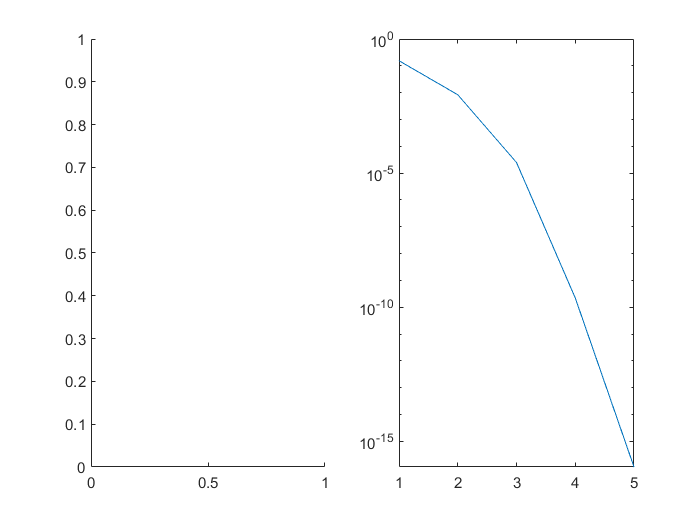

format % reset to default for number display



   
eps_abs = 1e-5;
eps_step = 1e-5;
a = 0.0;
b = 2.0;
g=0;
while (b - a >= eps_step || ( abs( f(a) ) >= eps_abs && abs( f(b) )  >= eps_abs ) )
    c = (a + b)/2;
    if ( f(c) == 0 )
       break;
    elseif ( f(a)*f(c) < 0 )
       b = c;
    else
       a = c;
    end
    g = g+1;
end



figure;
subplot(1,2,1)
%make here your first plot
subplot(1,2,2)
semilogy(newterr)

function y = f(x)
   y = x.^3 - 2; 
end